## 0. Parámetros Físicos

Long = 20;              % Distancia de fibra en km (Ej. 25km, 50km)
alpha = 0.2;         % Atenuación de la fibra estándar (dB/km)
Va = 4;              % Varianza de modulación de Alice (VA). Típico: 4-20 SNU.
T = 10^(-alpha * Long / 10) %Transmitancia

T = 0.3981

% Parámetros de Ruido
vel = 0.05;          % Ruido electrónico del detector (0.05 = 5% del shot noise)
xi = 0.01;           % Ruido de exceso a la entrada (Excess Noise). Típico: 0.01
% Tamaños
n = 26112

n = 26112

max_iter = 200

max_iter = 200

N_pulsos = 100000 %Número de pulsos que vamos a generar (tiene que ser mayor para generar varias veces)

N_pulsos = 100000

## 1. Generación (Alice)

%Generamos los números Aleatorios de Alice
q_Alice = sqrt(Va)*randn(N_pulsos, 1)

q_Alice =     0.1395
    1.5055
   -3.4720
   -4.4328
   -0.5875
   -1.6576
   -4.1963
   -2.5279
    4.2557
   -2.2546
   -0.2823
    0.8973
   -4.3444
   -0.7836
   -0.8613


p_Alice = sqrt(Va)*randn(N_pulsos, 1)

p_Alice =    -1.4005
   -0.7187
   -1.2357
   -1.7167
    0.6755
    3.4991
   -0.5746
    0.8234
    3.5315
   -1.9929
   -3.3027
   -0.1369
    0.1099
    0.8963
   -2.8830


Xa = zeros(2 * N_pulsos, 1)

Xa =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Intercalado (Interleaving)
Xa(1:2:end) = q_Alice; % Posiciones impares: Q
Xa(2:2:end) = p_Alice; % Posiciones pares: P

%Simulación de Ruido
%variables de ruido
var_noise = 1 + vel + T * xi %varianza del ruido

var_noise = 1.0540

std_noise = sqrt(var_noise) %desviación típica del ruido

std_noise = 1.0266

% ruido como tal
z_noise_p = std_noise * randn(N_pulsos, 1)

z_noise_p =    -0.1040
    0.9171
    1.2012
    0.9161
    0.2135
   -1.0555
    0.0105
   -1.0366
   -0.8061
   -0.6221
    1.1857
    1.5516
    0.6562
    0.3738
   -0.1761


z_noise_q = std_noise * randn(N_pulsos, 1)

z_noise_q =    -1.7458
   -0.7632
    1.6756
   -2.9033
   -0.7123
    1.2832
   -0.0591
   -1.1730
    0.3564
    0.6438
   -0.7500
   -0.1596
   -1.5456
    0.4723
   -0.5184


## 2. Recepción (Bob)

p_Bob = sqrt(T) * p_Alice + z_noise_p

p_Bob =    -0.9876
    0.4637
    0.4216
   -0.1670
    0.6397
    1.1523
   -0.3520
   -0.5171
    1.4221
   -1.8796
   -0.8982
    1.4652
    0.7255
    0.9394
   -1.9951


q_Bob = sqrt(T) * q_Alice + z_noise_q

q_Bob =    -1.6578
    0.1867
   -0.5150
   -5.7002
   -1.0830
    0.2374
   -2.7067
   -2.7680
    3.0416
   -0.7787
   -0.9282
    0.4066
   -4.2867
   -0.0221
   -1.0618


Yb = zeros(2*N_pulsos,1)

Yb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Yb(1:2:end) = q_Bob; % Posiciones impares: Q
Yb(2:2:end) = p_Bob; % Posiciones pares: P

## 2.1 Representación de Valores y cálculo parámetros interesantes

%Todo esto es muy extra de chati
% Potencia de señal recibida / Potencia de ruido total
Signal_Power_Rx = T * Va;
Noise_Power_Rx  = var_noise;

SNR_lineal = Signal_Power_Rx / Noise_Power_Rx;
SNR_dB = 10 * log10(SNR_lineal)

SNR_dB = 1.7923

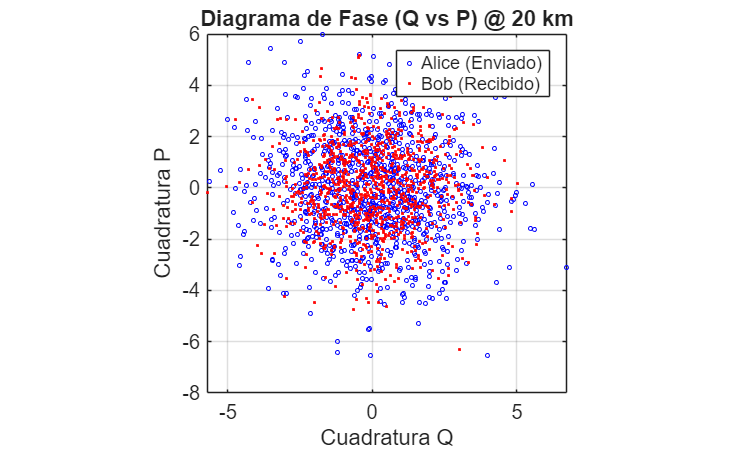


figure;
% Mostramos solo los primeros 1000 puntos para no saturar la gráfica
plot(q_Alice(1:1000), p_Alice(1:1000), 'bo', 'MarkerSize', 2); hold on;
plot(q_Bob(1:1000), p_Bob(1:1000), 'r.', 'MarkerSize', 4);
legend('Alice (Enviado)', 'Bob (Recibido)');
title(['Diagrama de Fase (Q vs P) @ ' num2str(Long) ' km']);
xlabel('Cuadratura Q'); ylabel('Cuadratura P');
axis square; grid on;

## 3. Generación de H

%% 3. GENERACIÓN DE MATRIZ H (LDPC 5G NR)
% -------------------------------------------------------------------------
% Cargar Base Graph 1 del estándar 5G NR-LDPC
Z = 384;                            % Factor de lifting
baseGraphFile = 'C:\Users\usser\OneDrive - Universidad Politécnica de Madrid\INDUSTRIALES I DANI\GRADO\TFG\LDPC\NR-LDPC-BG-master\NR-LDPC-BG-master\NR_1_1_384.txt';

% Leer la matriz base desde archivo
BaseGraph = load(baseGraphFile);
[mb, nb] = size(BaseGraph);         % BG1: 46×68

% Dimensiones finales de H
M = mb * Z;                         % 17,664 filas (ecuaciones de paridad)
N_ldpc = nb * Z;                    % 26,112 columnas (bits totales)

fprintf('Matriz Base: %d×%d, Z=%d → H: %d×%d\n', mb, nb, Z, M, N_ldpc);

Matriz Base: 46×68, Z=384 → H: 17664×26112



% Expansión de la matriz (lifting) usando matrices sparse
% Pre-calcular número de elementos no nulos para eficiencia
num_nonzero_blocks = sum(BaseGraph(:) >= 0);
nnz_total = num_nonzero_blocks * Z;

% Pre-asignar arrays para construcción sparse eficiente
row_indices = zeros(nnz_total, 1);
col_indices = zeros(nnz_total, 1);
values = ones(nnz_total, 1);

idx = 1;
for i = 1:mb
    for j = 1:nb
        shift_val = BaseGraph(i, j);
        if shift_val >= 0
            % Índices de la submatriz identidad rotada
            row_base = (i-1) * Z;
            col_base = (j-1) * Z;
            
            % Generar índices de la identidad circulante
            for k = 1:Z
                row_indices(idx) = row_base + k;
                col_indices(idx) = col_base + mod(k - 1 + shift_val, Z) + 1;
                idx = idx + 1;
            end
        end
    end
end

% Construir matriz sparse
H = sparse(row_indices, col_indices, values, M, N_ldpc)

H = 17664×26112 sparse double matrix (121344 nonzeros)
        (78,1)              1
       (693,1)              1
       (948,1)              1
      (1261,1)              1
      (1589,1)              1
      (2110,1)              1
      (2411,1)              1
      (3064,1)              1
      (3150,1)              1
      (3475,1)              1
      (4561,1)              1
      (4916,1)              1
      (5064,1)              1
      (5619,1)              1
      (5904,1)              1
      (6653,1)              1
      (7536,1)              1
      (7878,1)              1
      (8803,1)              1
      (9303,1)              1
     (10298,1)              1
     (10915,1)              1
     (11746,1)              1
     (12571,1)              1
     (13211,1)              1
     (13999,1)              1
     (14792,1)              1
     (15570,1)              1
     (16400,1)              1
     (17201,1)              1
        (79,2)              1
       (694,2) 


fprintf('Matriz H generada: %d elementos no nulos (densidad: %.4f%%)\n', nnz(H), 100*nnz(H)/(M*N_ldpc));

Matriz H generada: 121344 elementos no nulos (densidad: 0.0263%)


## 4. Estimación de parámetros

%Generamos los distintos vectores que necesitamos
Xr = Xa(1:2:2*n) %Los valores de X que vamos a usar para la reconciliación

Xr =     0.1395
    1.5055
   -3.4720
   -4.4328
   -0.5875
   -1.6576
   -4.1963
   -2.5279
    4.2557
   -2.2546
   -0.2823
    0.8973
   -4.3444
   -0.7836
   -0.8613


Xp = Xa(2:2:2*n) %Los valores de X que vamos a usar para la estimación de parámetros

Xp =    -1.4005
   -0.7187
   -1.2357
   -1.7167
    0.6755
    3.4991
   -0.5746
    0.8234
    3.5315
   -1.9929
   -3.3027
   -0.1369
    0.1099
    0.8963
   -2.8830


Yr = Yb(1:2:2*n) %Los valores de Y que vamos a usar para la reconciliación

Yr =    -1.6578
    0.1867
   -0.5150
   -5.7002
   -1.0830
    0.2374
   -2.7067
   -2.7680
    3.0416
   -0.7787
   -0.9282
    0.4066
   -4.2867
   -0.0221
   -1.0618


Yp = Yb(2:2:2*n) %Los valores de Y que vamos a usar para la estimación de parámetros

Yp =    -0.9876
    0.4637
    0.4216
   -0.1670
    0.6397
    1.1523
   -0.3520
   -0.5171
    1.4221
   -1.8796
   -0.8982
    1.4652
    0.7255
    0.9394
   -1.9951


%Estimamos T
Cov_xy = cov(Xp, Yp) %matriz de covarianzas

Cov_xy =     4.0422    2.5415
    2.5415    2.6560


covarianza_xy = Cov_xy(1, 2) 

covarianza_xy = 2.5415

varianza_x = var(Xp)

varianza_x = 4.0422

T_estimada = (covarianza_xy / varianza_x)^2

T_estimada = 0.3953


%Estimación del ruido residual
sigma2 = var(Yp - sqrt(T_estimada)*Xp)

sigma2 = 1.0580

z_est = (sigma2 - 1 - vel)/T_estimada

z_est = 0.0203

## 5. Cálculo del Síndrome

%Calculamos el síndrome
Kb = zeros(n, 1)

Kb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Kb(Yr <= 0) = 1; 
Kb(Yr > 0)  = 0;
S = mod(H * Kb, 2);

## 6. Reconciliación Inversa

%% 6. Reconciliación Inversa (Alice) - Scaled Min-Sum con Síndrome Vectorizado

% --- 6.1. Parámetros e Inicialización ---
alpha_sms = 0.75; % Factor de escalado
max_iter = 60;
exito = 0;
m = size(H, 1); % Número de Nodos de Chequeo (17664)
n = size(H, 2); % Número de Nodos de Variable (26112)

% LLR inicial (Ajusta el signo según tu convención si es necesario)
LLR_in = (2 * sqrt(T_estimada) / sigma2) * Xr; 

% Preparamos índices para evitar recorrer la matriz entera
[rows, cols] = find(H); 
num_edges = length(rows);

% Inicializamos los mensajes de los Nodos de Variable (Lq)
Lq = LLR_in(cols); 

% Modificador de síndrome de Bob: Mapea S=0 -> 1 y S=1 -> -1
S_mod = 1 - 2 * S; 

%% --- 6.2. Bucle Iterativo ---
for iter = 1:max_iter
    
    % ==========================================================
    % PASO A: Nodos de Chequeo (CN -> VN) - VECTORIZADO
    % ==========================================================
    
    % --- Procesamiento de Signos ---
    sign_Lq = sign(Lq);
    sign_Lq(sign_Lq == 0) = 1; % Evitar ceros
    
    % Truco de paridad: 1 -> 0, -1 -> 1. Sumamos y hacemos mod 2.
    sign_bin = (1 - sign_Lq) / 2; 
    sum_signs = accumarray(rows, sign_bin, [m, 1]); 
    prod_signs_total = 1 - 2 * mod(sum_signs, 2); % Volvemos al dominio {1, -1}
    
    % El signo extrínseco para cada arista es el total dividido por el de la arista
    % (Como son 1 o -1, dividir es lo mismo que multiplicar)
    ext_sign = prod_signs_total(rows) .* sign_Lq;
    
    % ADAPTACIÓN DEL SÍNDROME: Multiplicamos por el modificador de Bob
    ext_sign = ext_sign .* S_mod(rows);
    
    % --- Procesamiento de Magnitudes (Min1 y Min2) ---
    mag_Lq = abs(Lq);
    
    % 1er Mínimo de cada nodo de chequeo
    min1 = accumarray(rows, mag_Lq, [m, 1], @min);
    
    % Identificamos qué aristas contienen ese mínimo exacto
    is_min1 = (mag_Lq == min1(rows));
    
    % 2do Mínimo: Penalizamos los min1 con infinito y volvemos a buscar
    mag_Lq_mod = mag_Lq;
    mag_Lq_mod(is_min1) = realmax; 
    min2 = accumarray(rows, mag_Lq_mod, [m, 1], @min);
    
    % Asignamos min1 a casi todas las aristas, y min2 a las que eran min1
    ext_mag = min1(rows); 
    ext_mag(is_min1) = min2(rows(is_min1));
    
    % Mensaje final de Nodos de Chequeo (Lr)
    Lr = alpha_sms .* ext_sign .* ext_mag;
    
    % ==========================================================
    % PASO B: Nodos de Variable (VN -> CN) - VECTORIZADO
    % ==========================================================
    
    % Sumamos todos los mensajes Lr entrantes para cada Nodo de Variable
    sum_Lr = accumarray(cols, Lr, [n, 1]); 
    
    % Creencia total
    LLR_total = LLR_in + sum_Lr;
    
    % Extrínseco para la siguiente iteración
    Lq = LLR_total(cols) - Lr;
    
    % ==========================================================
    % PASO C: Decisión Dura
    % ==========================================================
    
    Ka = zeros(n, 1);
    Ka(LLR_total < 0) = 1; 
    Ka(LLR_total >= 0) = 0;
    
    % ==========================================================
    % PASO D: Comprobación Temprana del Síndrome
    % ==========================================================
    
    S_estimado = mod(H * Ka, 2);
    
    if isequal(S_estimado, S)
        exito = 1;
        fprintf('¡Éxito! Reconciliación lograda en la iteración %d.\n', iter);
        break;
    end
    
end

%% --- 6.3. Resultados ---
if exito == 0
    fprintf('Fallo en la reconciliación tras %d iteraciones.\n', max_iter);
end

Fallo en la reconciliación tras 60 iteraciones.
